clc;
clear all;
close all;

# Generation of data

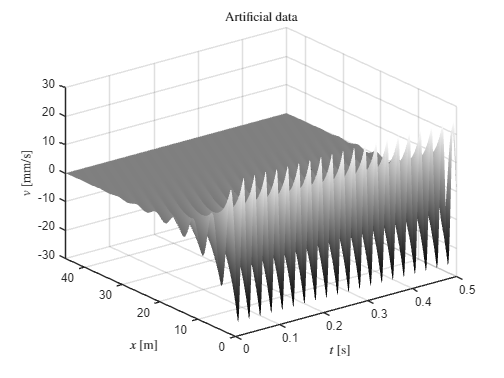

noise_lev = 1e-5;

dt = 0.001;

t = 0:dt:1;

t_plot = .5;

x = 0:0.1:45;

freq = 40; %Hz

L = 5;%5; % wave length

V = freq*L;% wave velocity

omega = 2*pi*freq; % circular freq

u0 = 0.0001; % amplitude

psi = 1.5;

alpha = (psi*freq)/(2*V);

dt = t(2)-t(1);

U_damped = zeros(length(x),length(t));
V_damped = zeros(length(x),length(t));

k = omega/V;

for j=1:length(t)
    U_damped(:,j) = u0*exp(1i*(omega*t(j)-x*k)).*exp(-alpha*x); 
    V_damped(:,j) = u0*1i*omega*exp(1i*(omega*t(j)-x*k)).*exp(-alpha*x); 
end


indx_plot = find(t==t_plot);
[X_mesh,Y_mesh] = meshgrid(t(1:indx_plot),x);
surf(X_mesh,Y_mesh,real(V_damped(:,1:indx_plot))*1000);
shading interp; 
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [m]','Interpreter','latex'); 
yticks(min(x(:)):10:max(x(:)));  % Adjust the step size as needed (1 here is the step size)
% yl.Position(1) = yl.Position(1) + .1;  % move the label 0.1 data-units further down
zlabel('$v$ [mm/s]','Interpreter','latex')
colormap("gray")
title('Artificial data','Interpreter','latex')

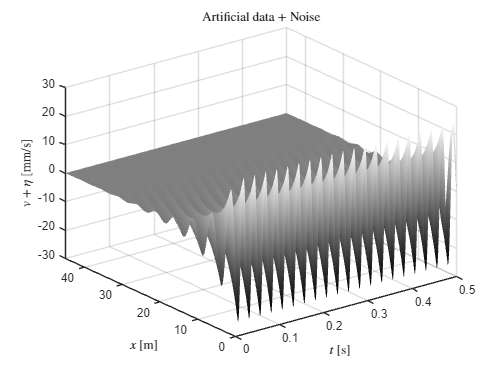


%% Inclusion of noise



V_noisy = V_damped + noise_lev*randn(size(V_damped));
surf(X_mesh,Y_mesh,real(V_noisy(:,1:indx_plot))*1000);

shading interp; 
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [m]','Interpreter','latex'); 
yticks(min(x(:)):10:max(x(:)));  % Adjust the step size as needed (1 here is the step size)

zlabel('$v$ + $\eta$ [mm/s]','Interpreter','latex')
colormap("gray")
title('Artificial data + Noise','Interpreter','latex')

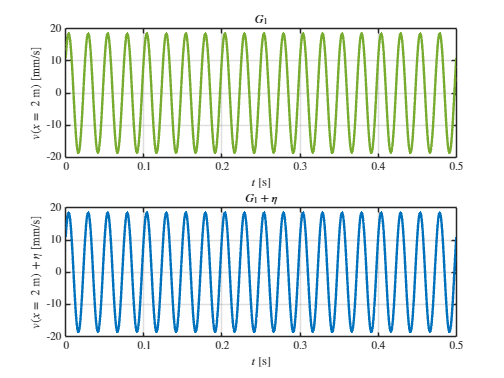

%% Simulation of geophones
color_noisefree ="#77AC30";
Data_V = real(V_damped);
Data_V_noisy = real(V_noisy);

meas_points = [2  35]; %[m]

idx_meas_points = zeros(1, length(meas_points));

t_plot_geo = 0.5;

for i = 1:length(meas_points)
    [~, idx_meas_points(i)] = min(abs(x - meas_points(i)));
end

sim_geophones = Data_V(idx_meas_points,:);
sim_geophones_noisy = Data_V_noisy(idx_meas_points,:);

indx_plot_geo = find(t==t_plot_geo);

fig4 = figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(1,1:indx_plot_geo)*1000,'LineWidth',2,'Color',color_noisefree)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
%title("$v$ at $x$ = "+int2str(meas_points(1))+" m",'Interpreter','latex')
% ylim([-30 30])
set(gca,'TickLabelInterpreter','latex')
title('$G_1$', 'Interpreter','latex')
grid on
subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(1,1:indx_plot_geo)*1000,'LineWidth',2)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) + $\eta$ [mm/s]",'Interpreter','latex'); 
%title("$v$ + noise at $x$ = "+int2str(meas_points(1))+" m",'Interpreter','latex')
% ylim([-30 30])
set(gca,'TickLabelInterpreter','latex')
grid on
title('$G_1+\eta$', 'Interpreter','latex')

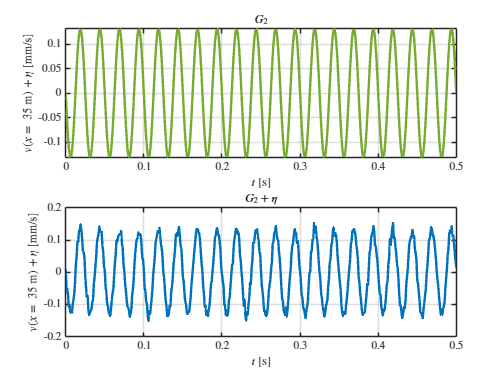




fig5 = figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(2,1:indx_plot_geo)*1000,'LineWidth',2,'Color',color_noisefree)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) + $\eta$ [mm/s]",'Interpreter','latex'); 
%title("$v$ at $x$ = "+int2str(meas_points(2))+" m",'Interpreter','latex')
% ylim([-30 30])
set(gca,'TickLabelInterpreter','latex')
title('$G_2$', 'Interpreter','latex')
grid on
subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(2,1:indx_plot_geo)*1000,'LineWidth',2)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) + $\eta$ [mm/s]",'Interpreter','latex'); 
grid on
% title("$v$ + noise at $x$ = "+int2str(meas_points(2))+" m",'Interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
title('$G_2+\eta$', 'Interpreter','latex')

## Standard DMD

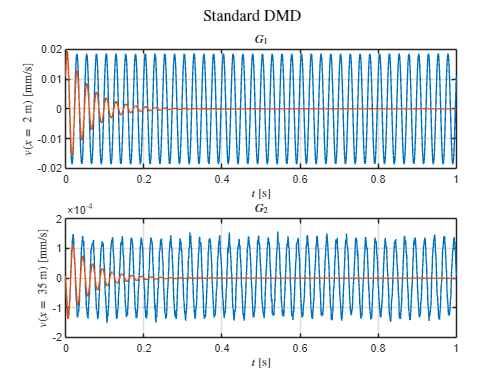

% Rank truncation
r = 2;
f = sim_geophones_noisy;
X1 = f(:,1:end-1); X2 = f(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U, S, V] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde_Standard = Ur' * X2 * Vr *Sr^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W, D] = eig(Atilde_Standard);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi = X2 * Vr / Sr * W;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda = diag(D);
omega = log(lambda) / dt;

% Determine the initial condition (b) in DMD space
b = Phi \ X1(:, 1);

% DMD prediction
f_dmd = real(Phi*(b.*exp(omega*t)));

% Plots
figure;
subplot(2,1,1)
plot(t,f(1,1:end))
hold on
plot(t,f_dmd(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(2,1,2)
plot(t,f(2,1:end))
hold on
plot(t,f_dmd(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')



sgtitle('Standard DMD','Interpreter','latex')

## Forward-backwards DMD

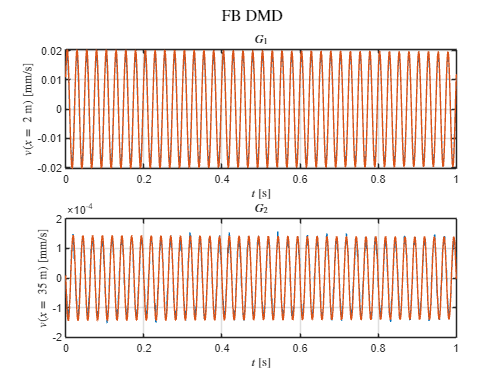

%% DMD for clean signal

% Rank truncation
r = 2;
f = sim_geophones_noisy;
X1 = f(:,1:end-1); X2 = f(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U_f, S_f, V_f] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur_f = U_f(:, 1:r);
Sr_f = S_f(1:r, 1:r);
Vr_f = V_f(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
f_Atilde = Ur_f' * X2 * Vr_f *Sr_f^(-1);

[U_b, S_b, V_b] = svd(X2, "econ");

Ur_b = U_b(:, 1:r);
Sr_b = S_b(1:r, 1:r);
Vr_b = V_b(:, 1:r);

b_Atilde = Ur_b' * X1 * Vr_b *Sr_b^(-1);

Atilde_FB = (f_Atilde*inv(b_Atilde))^0.5;

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W_fb, D_fb] = eig(Atilde_FB);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_fb = X1 * Vr_f / Sr_f * W_fb;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda_fb = diag(D_fb);
omega_fb = log(lambda_fb) / dt;

% Determine the initial condition (b) in DMD space
b_fb = Phi_fb \ X1(:, 1);

% DMD prediction
f_dmd_fb = real(Phi_fb*(b_fb.*exp(omega_fb*t)));

% Plots
figure;
subplot(2,1,1)
plot(t,f(1,1:end))
hold on
plot(t,f_dmd_fb(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(2,1,2)
plot(t,f(2,1:end))
hold on
plot(t,f_dmd_fb(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')



sgtitle('FB DMD','Interpreter','latex')